# 4CCE1MCP - Control System Design

*© Copyright of King's College London, Dept of Engineering 2022*

**Learning Objectives**

- Characterise the behaviour of a system using data-driven and model-based methods. 

- Implement an open-loop controller for a single-input, single-output system. 

- Critique the limitations of open-loop control. 

- Implement a feedback controller for a single-input, single-output system. 

- Implement a feedback controller for a vehicle. 

- Implement a logic-driven controller for task planning. 

## Motor Control

In this first section you will examine how to control a brushed DC motor using a PWM signal. The motor spins a propeller attached to its shaft at a rate $\Omega$  and generates a thrust force $T$ aligned with its rotational axis. 

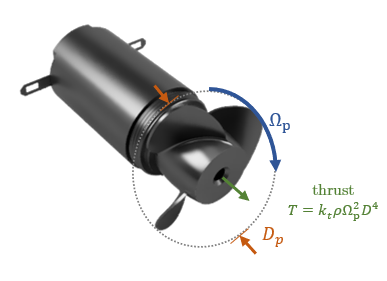               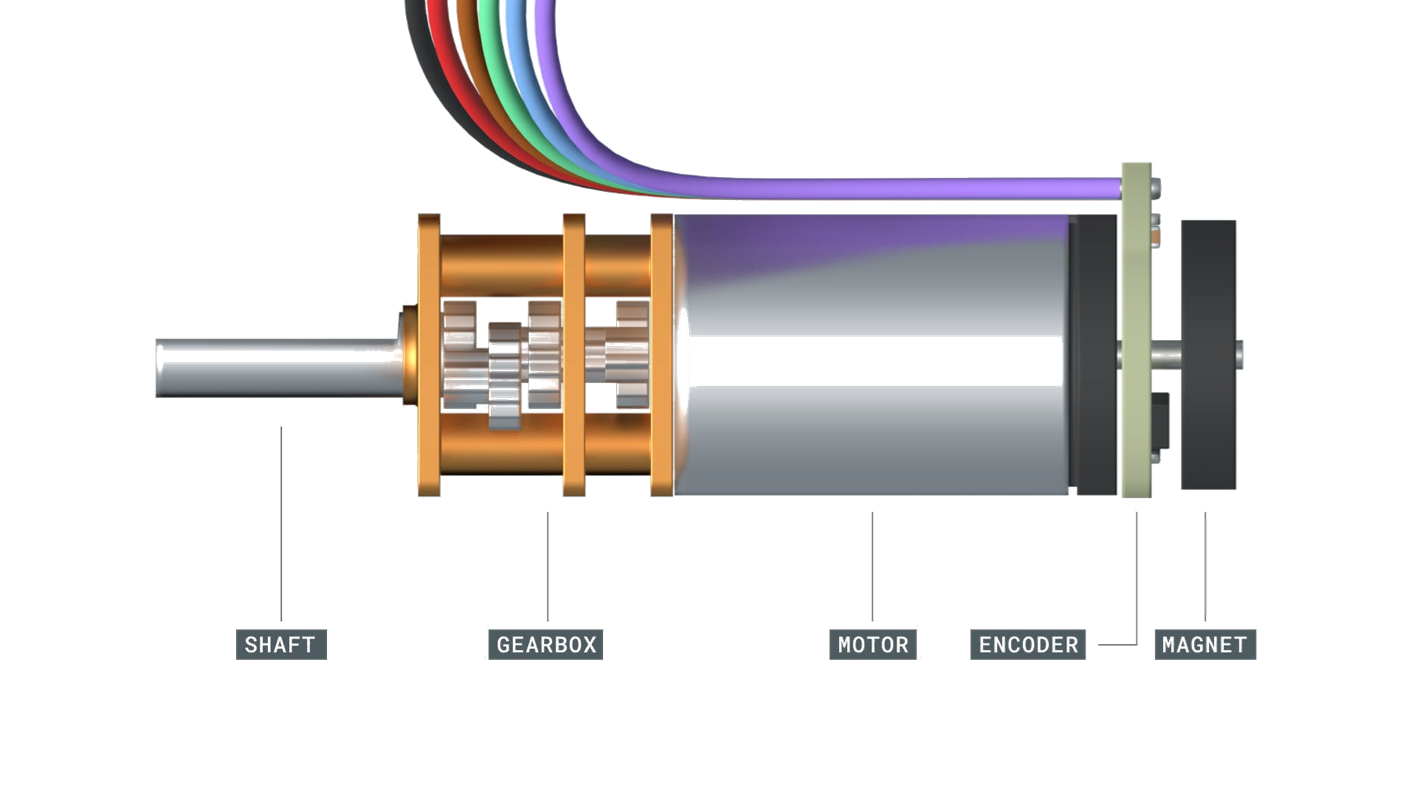

To adequately maneuver the ship, you will want to regulate how much thrust is generated by the propeller using a PWM signal. We will consider different approaches for how to do so. 

### PWM

The brushed DC motor is controlled by setting the duty cycle of the PWM signal used to regulate the voltage across the motor terminals. 

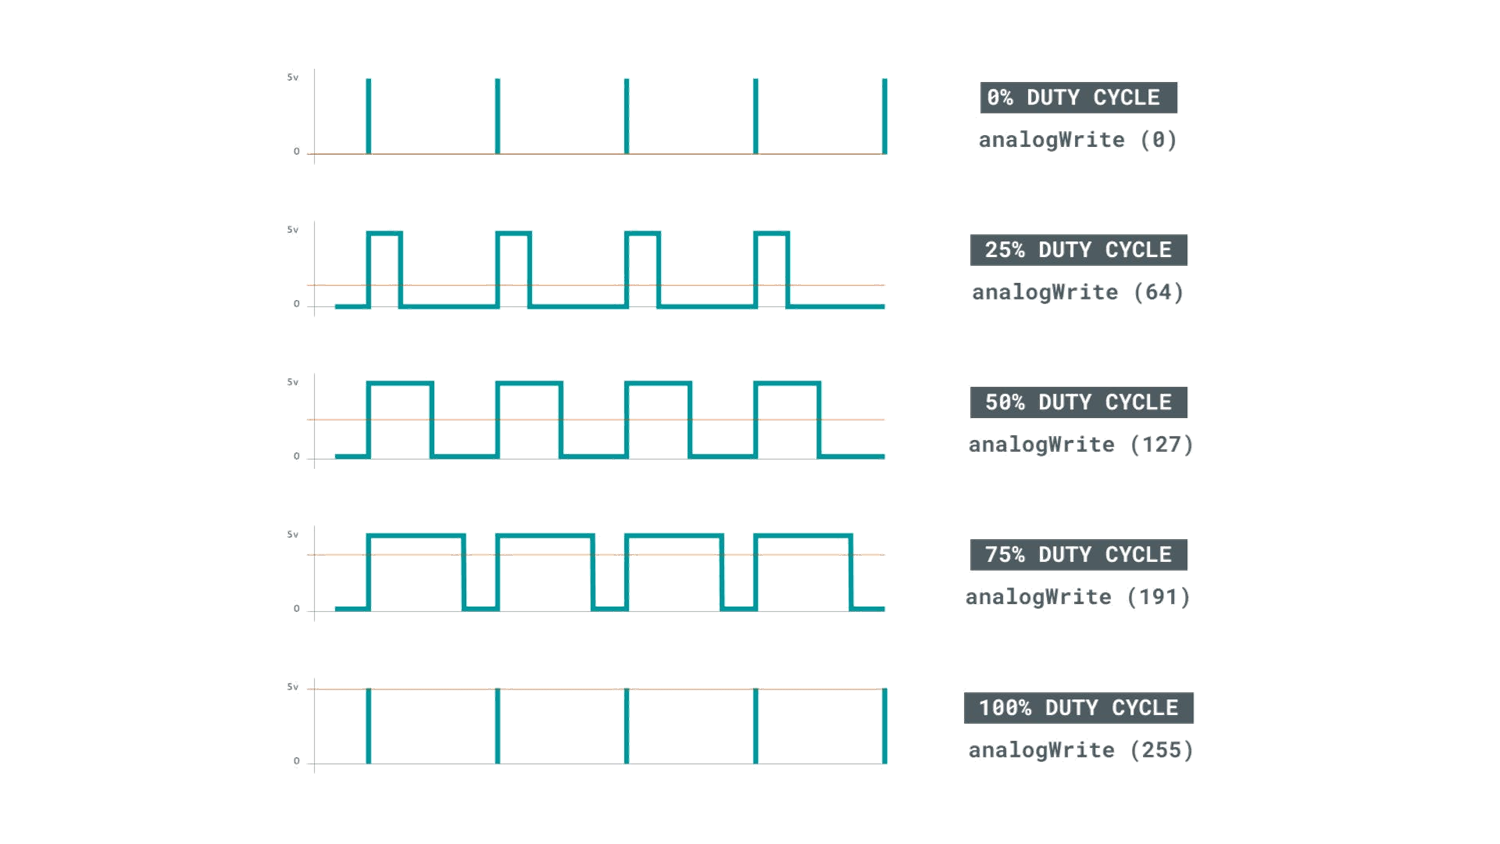

The switching dynamics of a pulse-width modulated (PWM) signal deliver an average voltage across the motor of:

        
$$\overline{V} = \overline{PWM} \times V_{max}$$


**Example: **Inspect the signal generated in the below model to compare PWM signals to their average value. Make sure to adjust the moving average filter window size to cover the length of the PWM period.  

  open_system('pwm')

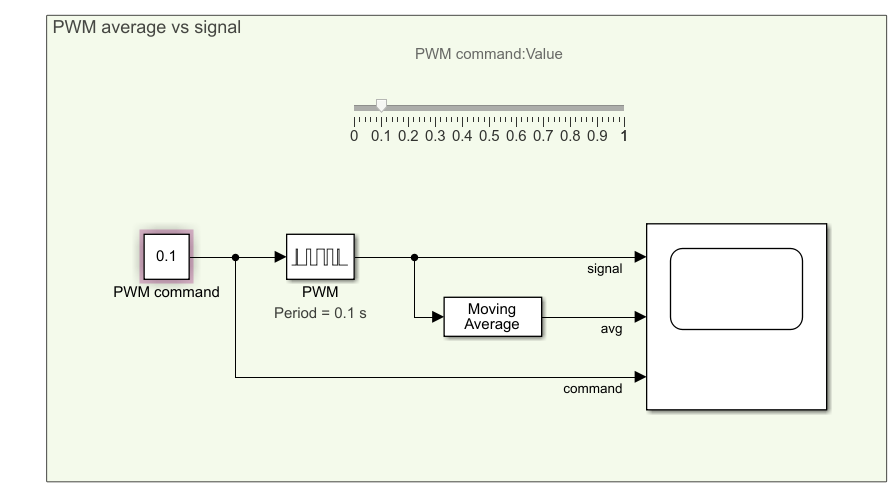

#### **PWM Motor Response**

**Exercise: **Open the model below to investigate how the DC motor that we modelled last week responds to a PWM signal. Vary the period of the PWM signal and comment on how it changes the oscillations. 

J = 1e-4;   % rotor inertia, kg.m^2
km = 0.1;   % motor constant, V.s/rad
R = 1;      % motor internal resistance, Ohm
Vmax= 7.2;  % DC voltage supply, V
L = 1e-2;   % motor internal inductance, H

  open_system('pwm_motor')

How does the angular velocity for the PWM-driven motor compare to that of the time-averaged model?

**Extra: **A real motor does not instantaneously respond to the change in voltage as charge needs to build up in inductive elements. The above Simulink model also contains a DC motor model that considers the inductance, $L$, of the motor armature. 

        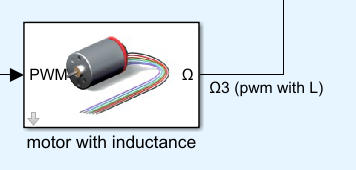

The governing equations that are implement in the block are given below:

        
$$\begin{cases}
V(t) = R \,i(t) + L \, \frac{di(t)}{dt}  + k_e \, \dot{\theta}(t) \\
\, \\
 J \, \ddot{\theta}(t) = k_t \, i(t) 
\end{cases}$$


Investigate how inductance changes the dynamics of the transient and steady state motor response. 

### Motor Characterisation

**Exercise: **Open the model below and record the values of angular velocity and thrust for $PWM=(0, 0.2, 0.4, 0.6, 0.8, 1.0)$. Plot the values for:

- rotor velocity against PWM. 

- thrust against rotor velocity. 

- thrust against PWM. 

  open_system("propeller_characterisation.slx")

**Solution: **The values from this exercise are stored in `motor_data.mat`

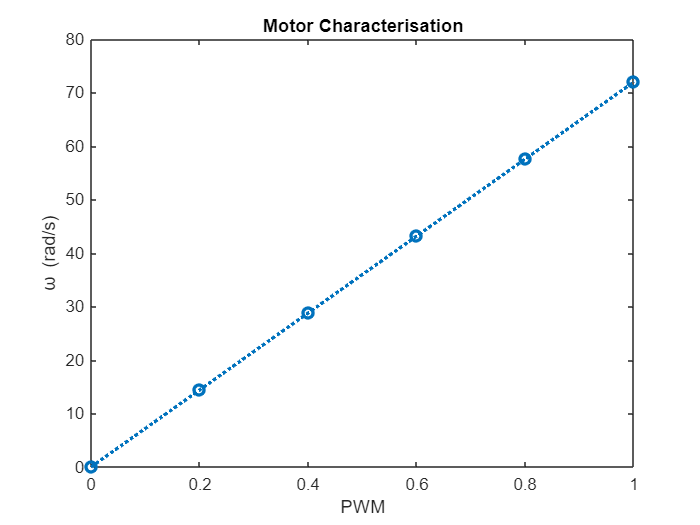

 

PWMInput = [0 0.2 0.4 0.6 0.8 1.0];
angularVelocity = [0 14.4 28.8 43.19 57.59 71.99];
thrustMeasured = [0 0.1037 0.4147 0.9326 1.658 2.592];

figure, plot(PWMInput, angularVelocity, 'o:',linewidth=2)
xlabel('PWM')
ylabel('\omega (rad/s)')
title('Motor Characterisation')

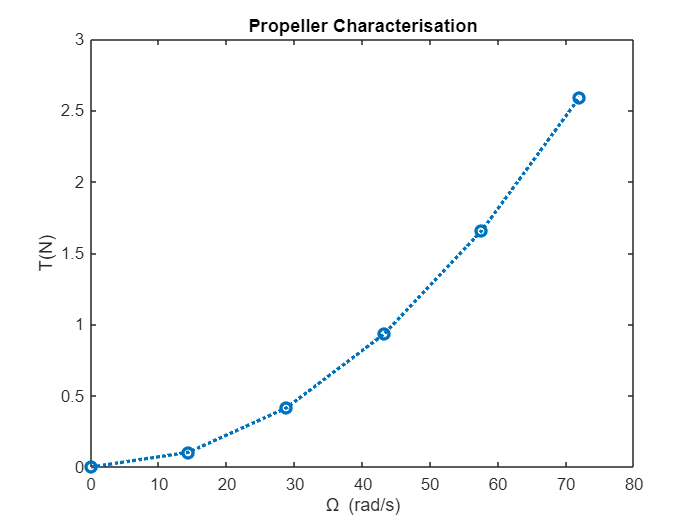

figure, plot(angularVelocity, thrustMeasured, 'o:',linewidth=2)
xlabel('\Omega (rad/s)')
ylabel('T(N)')
title('Propeller Characterisation')

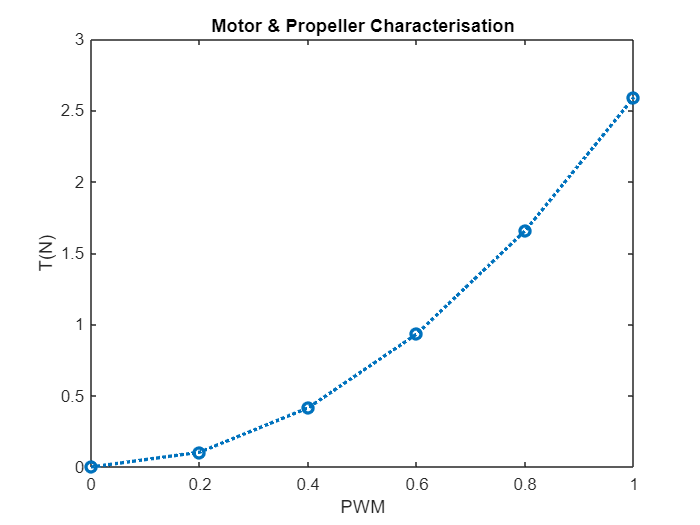

figure, plot(PWMInput, thrustMeasured, 'o:',linewidth=2)
xlabel('PWM')
ylabel('T(N)')
title('Motor & Propeller Characterisation')

### Open-loop Motor Control

The measurements obtained from the model will help us design a motor controller. In practice, you might obtain these measurements from a datasheet or from an experiment. 

We will want to relate the PWM signal to map to a required thrust, hereafter $T_{ref}$.

**Exercise: **Consider a simple proportional open-loop control law of the form:

        
$$PWM  = k \, T_{ref}$$


and estimate the value of $k$ from the data recorded in the previous exercise.

**Solution:**

 

k = PWMInput ./ thrustMeasured

k =        NaN    1.9286    0.9646    0.6434    0.4825    0.3858


k = mean(k, 'omitnan')

k = 0.8810

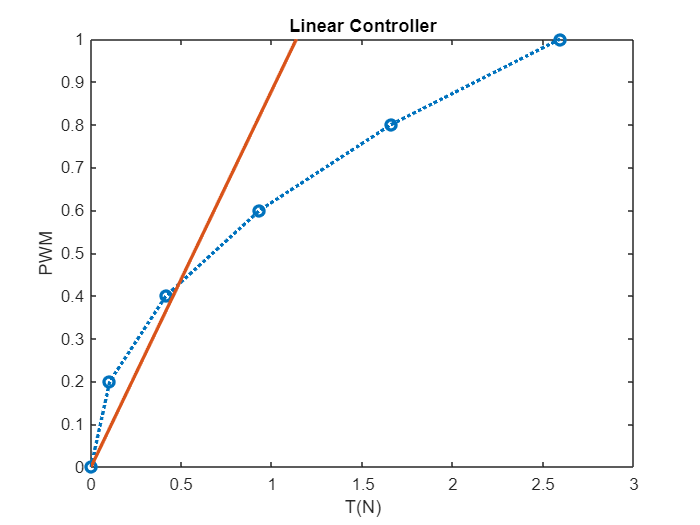


thrustTarget = PWMInput/k;

figure, plot(thrustMeasured, PWMInput, 'o:',linewidth=2)
hold on
plot(thrustTarget, PWMInput,linewidth=2)
% plot(thrustMeasured, PWMInput, 's-',linewidth=2)
ylabel('PWM')
xlabel('T(N)')
title('Linear Controller')

**Exercise:** Implement the control law from the previous exercise in the model below.

  open_system("propeller_openloop_control.slx")

#### Look-up tables

In the previous exercise, you will have noticed that the relationship between PWM and thrust is non-linear, and the proportional, open-loop controller did not provide an adequate fit over the operating range of the motor. 

In general, we will need to define a function, $f$ to relate the input (PWM) to output (thrust):

      
$$PWM = f(T_{ref})$$


A simple way to define the function $f$ is by using the PWM-Thrust data we collected earlier. 

**Example: **Look-up operations can be used to do so. 

By using measured data and interpolation, a look-up operation defines

load motor_data.mat

PWM = 0.91;
interpolationMethod = "linear";

thrust = interp1(PWMInput, thrustMeasured, PWM, interpolationMethod)

thrust = 2.1717

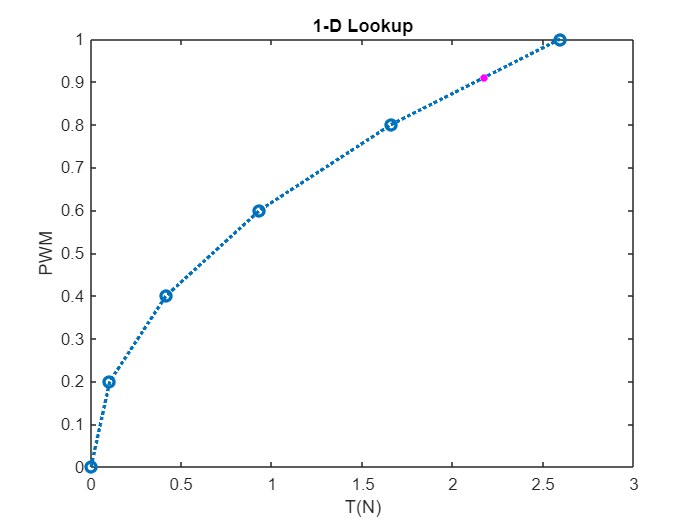

figure, plot(thrustMeasured, PWMInput, 'o:',linewidth=2)
hold on, scatter(thrust, PWM, 20, "magenta", "filled",linewidth=2)
ylabel('PWM')
xlabel('T(N)')
title('1-D Lookup')

**Exercise:** Implement a 1D lookup table controller for the propeller, using the 1-D Lookup Table Simulink block illustrated below. 

        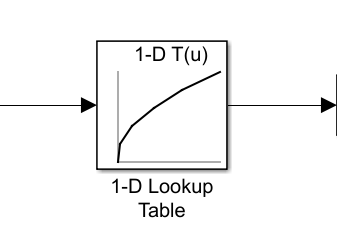

  open_system("propeller_lookup_control.slx")

#### **Model-based control**

Based on the modelling analysis we discussed last week's, our modelling assumptions where that:

- PWM is proportional to voltage, $PWM \propto V$

- Voltage is proportional to current, $V \propto I$

- Current is proportional to torque, $I \propto \tau$

- Torque is proportional to angular velocity squared, $\tau \propto \Omega^2$

- Thrust is proportional to torque, $T \propto \tau$

It follows that the PWM signal is proportional to the square root of thrust, $PWM \propto \, \sqrt{T_{ref}}$.

We will use this knowledge of the system to define a model-based controller. 

**Exercise: **Consider the control law:

        
$$PWM = k \, \sqrt{T_{ref}}$$


and estimate the value of $k$ from the data recorded in the previous exercise.

**Solution:**

k = mean(PWMInput./thrustMeasured.^0.5,'omitnan')

k = 0.6212

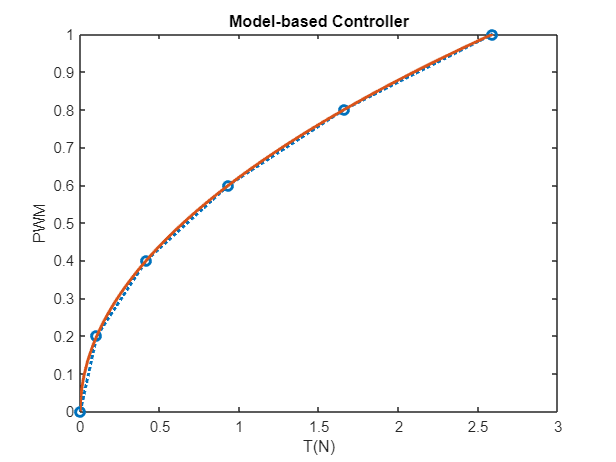

thrustTarget = ([0:0.01:1]/k).^2;

figure, plot(thrustMeasured, PWMInput, 'o:',linewidth=2)
hold on
plot(thrustTarget, [0:0.01:1],linewidth=2)
ylabel('PWM')
xlabel('T(N)')
title('Model-based Controller')

**Exercise:** Implement the model-based controller on the motor

  open_system("propeller_modelbased_control.slx")

#### Plant-model mismatch

It is often the case that we lack information about the plant that we want to control. This could be to imperfect models, that do not take into account secondary effects that affect the response.

In the following model, we include the effect of rotational aerodynamic drag induced by the propeller, $T_d \propto \Omega^2$. This arises from the viscous fluid forces acting on the propeller blades. 

**Exercise: **Retune the control gain $k$ from the previous exercise to improve the performance of the controller. How does the performance of the controller degrade over the operating range of the propeller. 

  open_system("propeller_modelbased_with_drag.slx")

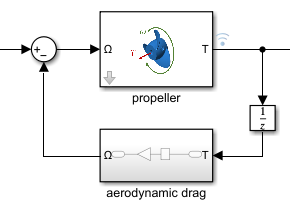

### Feedback (or Closed-loop) Motor Control

Control design can be improved by using sensor **measurements** of the system. The system is also often referred to as the *plant* in control design. Plant measurements are fed into the controller as part of a **control law. **

**In feedback control, **the control law is a function of the **error** between a **target** (also known as reference) and a **measured** state. 

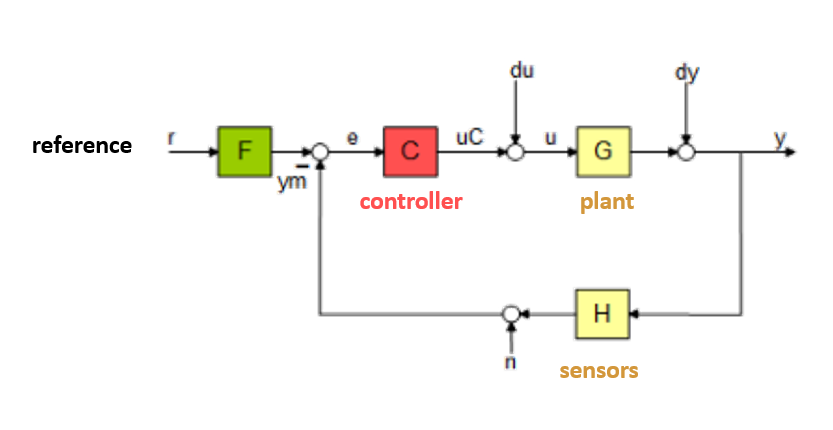

For example, a feedback error, $e$ for the motor could be defined as  $e = T_{ref}-T$.

### Proportional control

**Exercise: **Implement the control law in the model below:

        
$$PWM =  k_p \,(T_{ref}  -T)$$


  open_system("propeller_feedback_control.slx")

### Combined Feedback and Feedforward Control

**Exercise: **Implement the control law in the model below:

        
$$PWM =  k_p \,(T_{ref}  -T)+k_{ff} \sqrt{ T_{ref}}$$


  open_system("propeller_combined_feedback_feedforward.slx")

## Ship Control

Recall that the dynamics of the ship are governed by the equation:

        $m \ddot{x} = T_1 + T_2 - \frac{1}{2} C_d \, \rho \, A^2 \, \dot{x}  \,| \dot{x}|$   (balance of forces about $x$-axis)

        $J \ddot{\theta} = \frac{L(T_1-T_2)}{2} - \frac{1}{2} C_{\omega} \, \rho \, A^4 P \, \dot{\theta}  \,| \dot{\theta} |$    (balance of moment about $z$-axis)

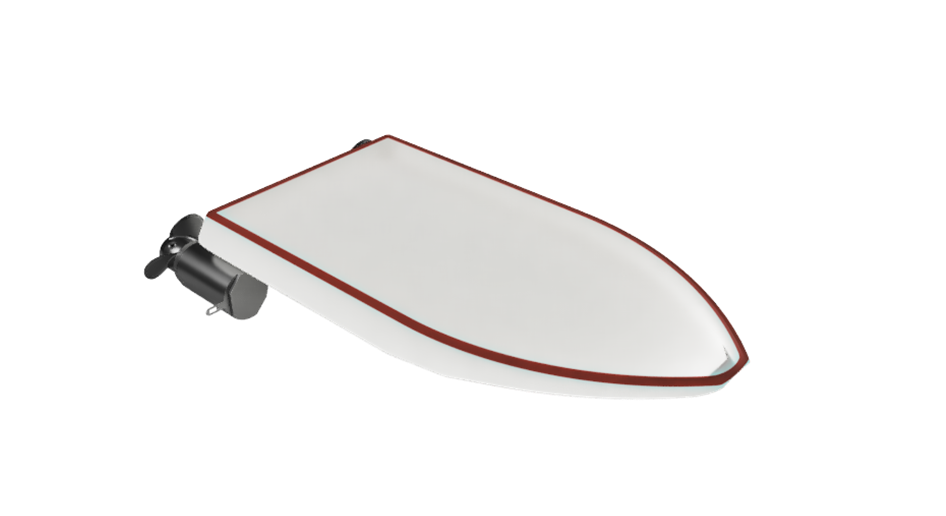

We will consider control laws to relate the thrusts $T_1$ and $T_2$ to the position of the ship. 

### Ship Feedback Control - 1D

#### **Proportional-derivative (PD) Control**

**Exercise: **Implement the control law in the model below:

        
$$PWM =  k_p \,(x_r  -x)$$


Comment on how the ship overshoots relative to the target position. 

  open_system("ship_1d_pcontrol.slx")

#### **Proportional-derivative (PD) Control**

**Exercise: **Implement the control law in the model below:

        
$$PWM = k_p(x_r  -x) - k_d\, \dot{x}$$


  open_system("ship_1d_pdcontrol.slx")

### Ship Kinematic Feedback Control - 2D

**Exercise:** Implement the control law below

        
$$v = k_{\rho} \, \rho$$


        
$$\omega = k_{\alpha} \, \alpha$$


where $\rho = \sqrt{ \left(\Delta y \right)^2 + \left(\Delta x \right)^2 }$

and $\alpha =  \beta - \theta  - \pi$

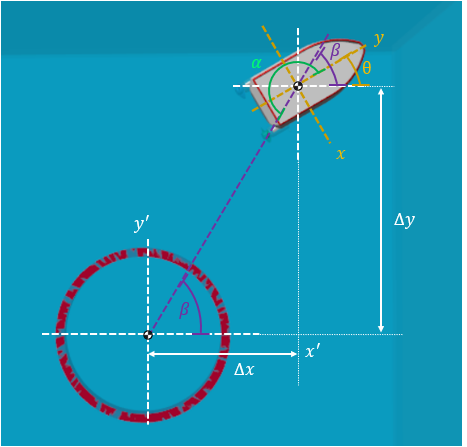

  open_system("ship_kinematic_control.slx")

### Ship Dynamic Feedback Control - 2D

**Exercise: **Implement the control law from the previous exercise in the dynamic model of the ship.

  open_system("ship_control.slx")

### Logic Driven Control

**Exercise: **Implement a logic-driven controller using Stateflow that sweeps the area, 

  open_system("ship_logic_driven_control.slx")

## Extra Credit: Logic-driven Control

You can use the Stateflow OnRamp course for reference to learn more about how to develop state machines for decision making systems. 

[https://uk.mathworks.com/learn/tutorials/stateflow-onramp.html](https://uk.mathworks.com/learn/tutorials/stateflow-onramp.html)